## Basics

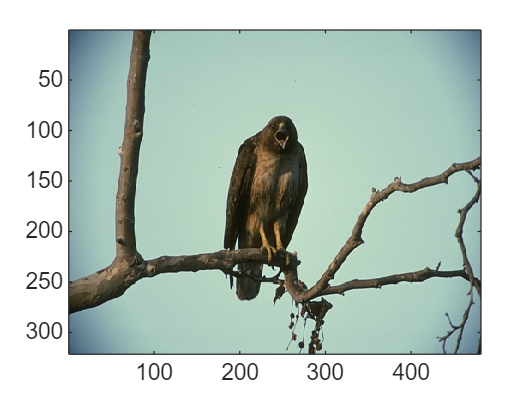

% Read an image
color_img = imread("dip/imgs/bird.jpg");

% Display an image
image(color_img) % as a graph

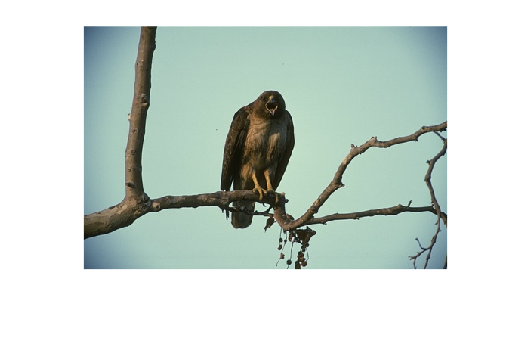

imshow(color_img); % as an image

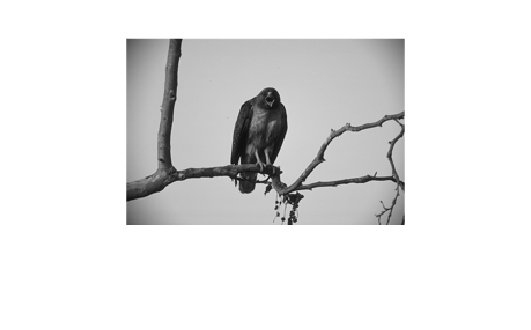

imageViewer(color_img); % in a toolbox

% Convert RGB image to grayscale
gray_img = rgb2gray(color_img);

% Resize image
gray_img_small = imresize(gray_img, 0.5);
imshow(gray_img_small);


% Save image as
imwrite(gray_img_small, "dip/imgs/bird-small.jpg");

## Test dip_rgb2gray

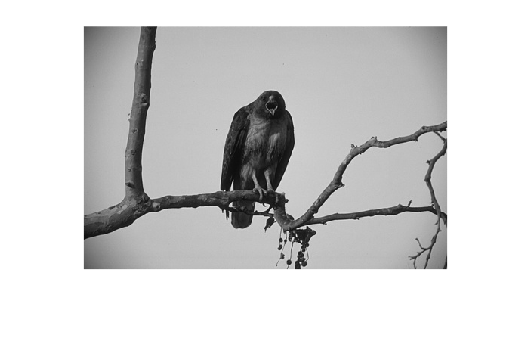

f = imread("dip\imgs\bird.jpg");
g = dip_rgb2gray(f);
imshow(g);

## Test dip_negative

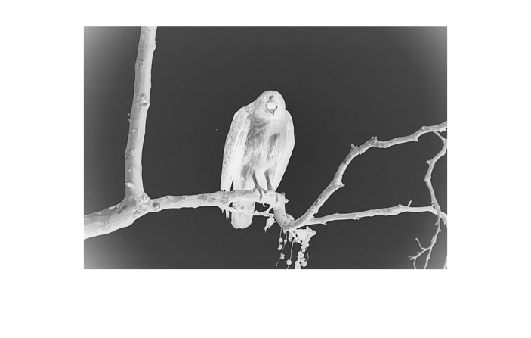

f = imread("dip\imgs\bird.jpg");
g = dip_rgb2gray(f);
g = dip_negative(g);
imshow(g);

## Test dip_chroma

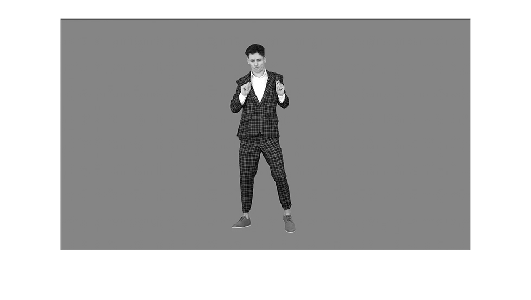

fg = rgb2gray(imread("dip\imgs\foreground.jpg"));
imshow(fg);

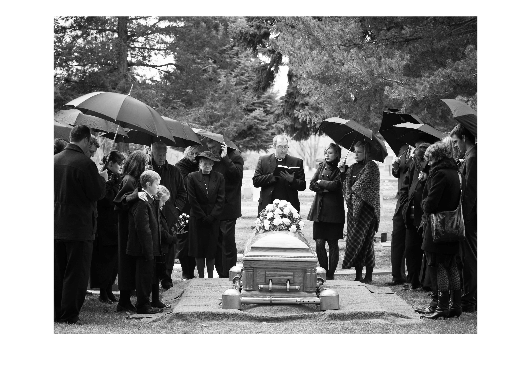

bg = rgb2gray(imread("dip\imgs\background.jpg"));
imshow(bg);

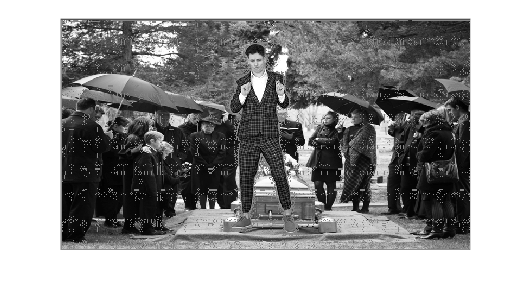

g = dip_chroma(fg, bg, 133); % 3rd argument according to fg's background color
imshow(g);